freq = [
40
50
60
70
80
90
100
120
140
200
280
450
600
700
800
900
1000
1320
1400
1700
2000
2500
3180
3400
3500
3600
3800
4000
4230
4500
4730
4900
5000
5300
5590
6000
6310
6500
6970
7400    
];

vout = [
0.7
1.22
1.84
2.68
3.56
4.92
5.76
7.76
8.8
7
6.16
5.52
6.56
6.96
5.2
3.76
5.28
6.32
6.96
4.4
3.28
2.4
1.92
1.84
1.28
0.62
0.5
0.42
1.12
2.8
1.5
0.98
1.36
2.36
2.76
3.72
4.46
4.16
2.32
1.22    
];

vin = [
0.592
0.616
0.584
0.584
0.616
0.624
0.664
0.68
0.616
0.584
0.576
0.576
0.568
0.568
0.576
0.552
0.552
0.552
0.552
0.584
0.552
0.584
0.632
0.616
0.624
0.616
0.8
0.616
0.96
0.96
0.98
1.06
1.08
0.8
0.8
0.82
0.8
0.8
0.82
0.78    
];

phase = [
153.6122
156.4218215
180
170.4059318
160.5287794
144.3146653
132.8334281
90
58.99728087
16.6015496
0
-9.594068227
-25.37693353
-41.8103149
-53.13010235
-51.05755873
-41.8103149
-90
-112.6198649
-160.5287794
-180
-240
-270
-340.5287794
-360
-383.5781785
-450
-513.6122
-540
-531.7867893
-630
-581.4096221
-540
-588.1896851
-630
-681.3178125
-720
-746.3878
-810
-953.1301024    
];

tran = vout./vin;

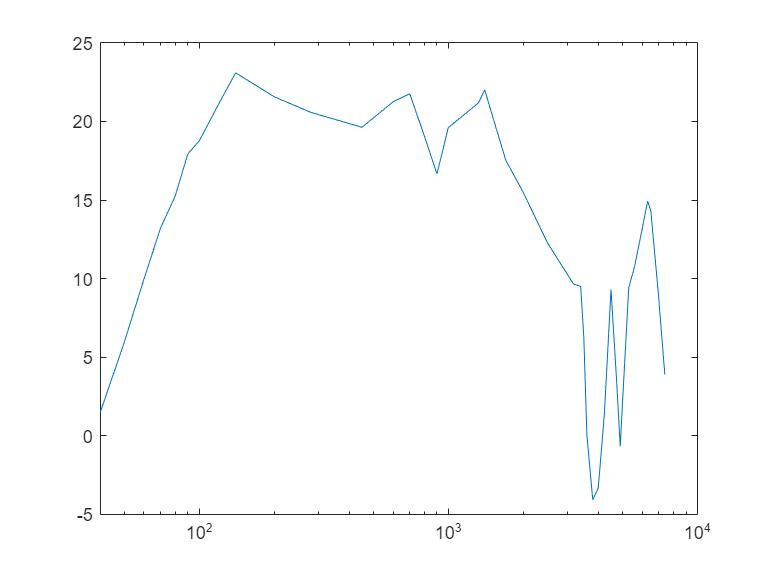

semilogx(freq, 20*log10(tran));

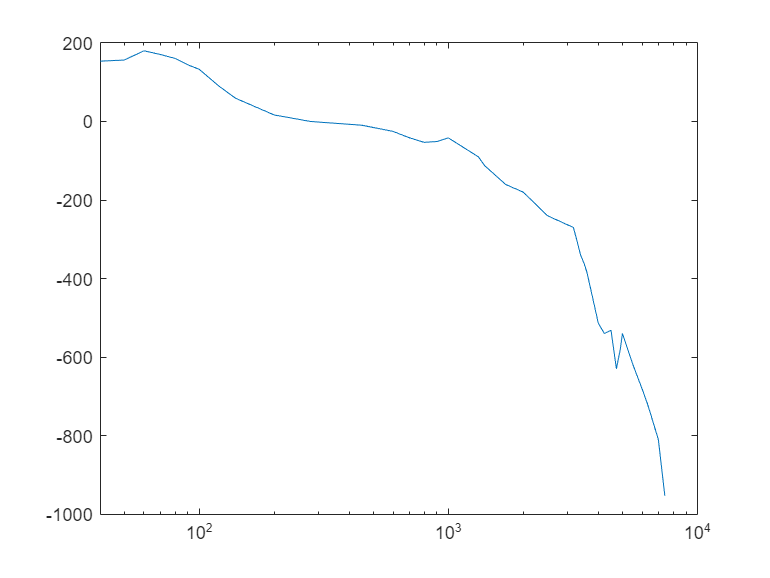

semilogx(freq, phase);

response = tran.*exp(1i*phase*pi/180);
Ts = 4*1e-5; % your sampling time
w=freq*2*pi; %convert Hz to rad/sec 

gfr = idfrd(response,w,Ts);

G=tfest(gfr,2);

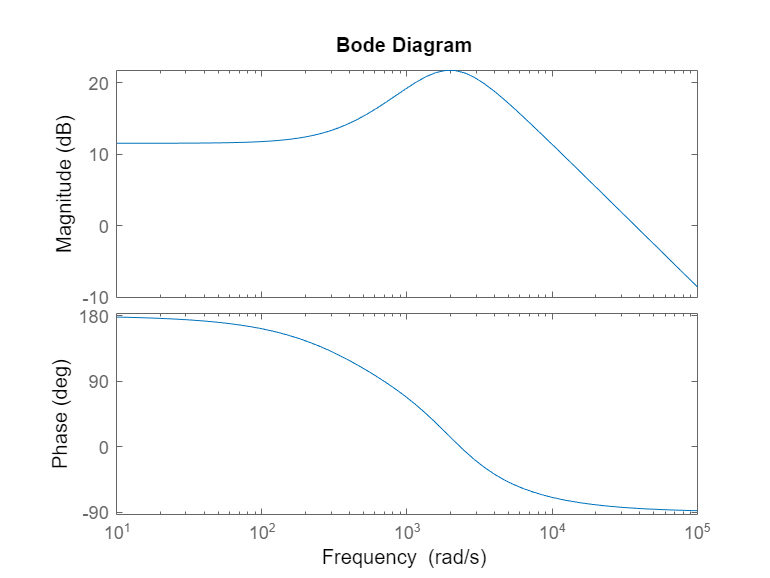

bodeplot(G)

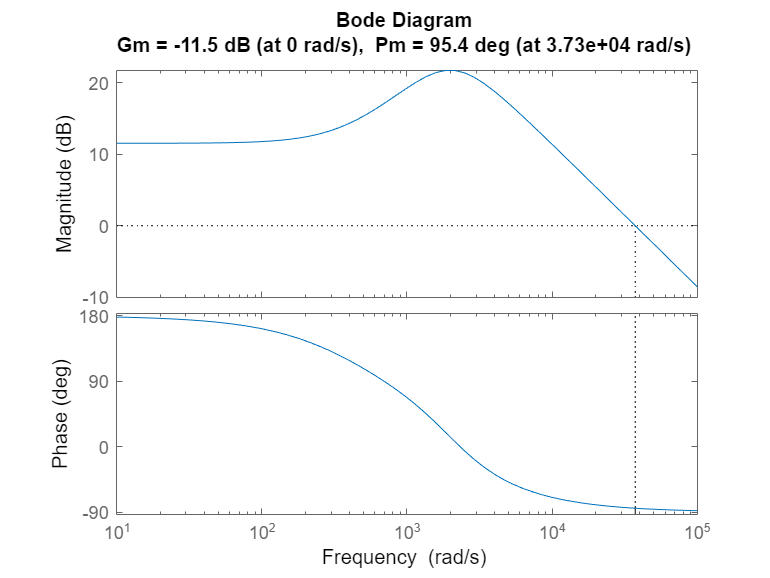

margin(G)

controlSystemDesigner(G)

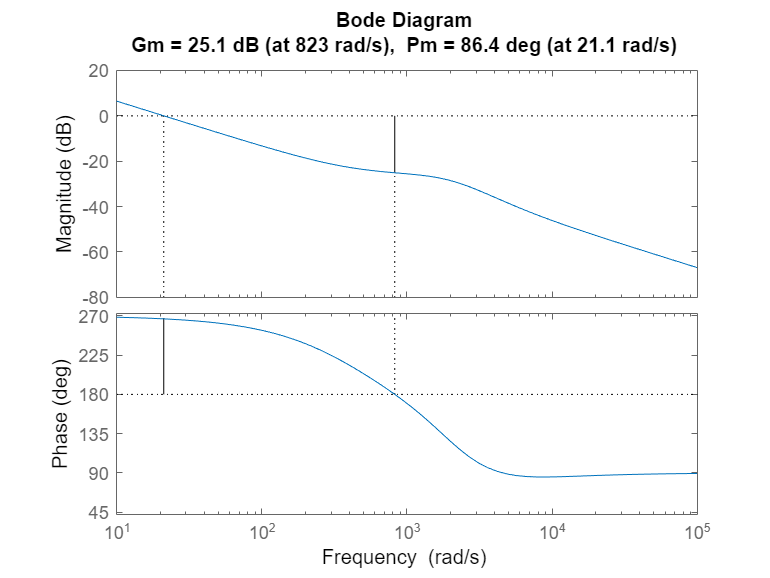


k = -0.0012;
c = 4656;
d = 1e-6;
comp = k*tf([1 c], [1 d]);
comp_sys = G*comp;
comp_sys_inclosedloop = comp_sys/(1 + comp_sys);
val = 20*log10(abs(evalfr(comp_sys,2*3.14*100*1j)));
margin(comp_sys);

val

val = -24.4022